## Load the matrix

getenv leading to MATLAB root

currentDir = pwd;

dataFolder = fullfile(currentDir, '..', '..', '..', '..', 'data', 'health', 'pet', ...
    '1_session_neuroimaging_basics', 'exercise2_matrix.csv');

## Create a vector of values

loadedMatrix = loadMatrixFromCSV(dataFolder);

valuesToMultiply = [2, 5, 10];

## Multiply the matrix with each value and print the maximum value

multiplyMatrixWithValues(loadedMatrix, valuesToMultiply);

Maximum value after multiplying by 2: 256.928284
Maximum value after multiplying by 5: 642.320709
Maximum value after multiplying by 10: 1284.641418


## Visualize the loaded matrix

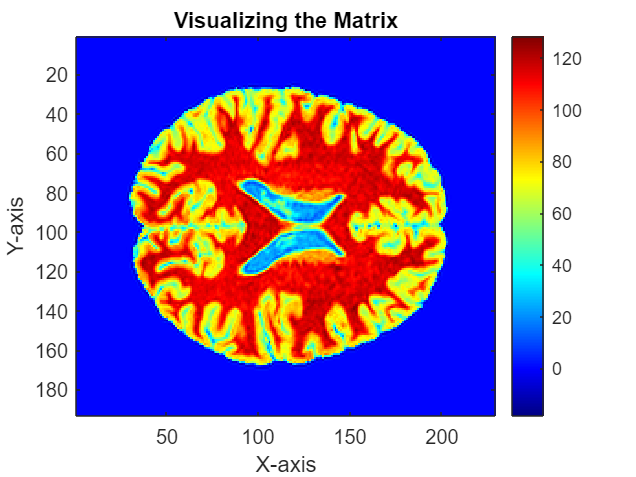

visualizeMatrix(loadedMatrix);


% Function to load a numeric matrix from a CSV file

function mtx = loadMatrixFromCSV(absolutePath)
mtx = table2array(readtable(absolutePath));
end

% Function to perform matrix multiplications with different values
function maxValues = multiplyMatrixWithValues(matrix, values)
numValues = length(values);
maxValues = zeros(1, numValues);

for i = 1:numValues
    result = matrix * values(i);
    maxAfterMultiplication = max(result, [], 'all');
    fprintf('Maximum value after multiplying by %d: %f\n', values(i), maxAfterMultiplication);
    maxValues(i) = maxAfterMultiplication;
end
end

% Function to calculate statistics on maximum values
function calculateStatistics(maxValues)
fprintf('Statistics on maximum values:\n');
fprintf('Mean: %f\n', mean(maxValues));
fprintf('Median: %f\n', median(maxValues));
fprintf('Standard Deviation: %f\n', std(maxValues));
end

% Function to visualize a matrix
function visualizeMatrix(matrix)
imagesc(matrix);
colormap('jet'); % You can choose a colormap of your preference
colorbar;
title('Visualizing the Matrix');
xlabel('X-axis');
ylabel('Y-axis');
end